# SCR grand average

Stimulus-locked grand average. For each trial, a baseline was created by averaging physiological time-series data from 3 seconds before the thermal stimulation onset.  A stimulus-locked physiological response was generated by subtracting the baseline value from the data in the 20-second period after the stimulation onset. 

clear all;
close all;

basedir = '/Users/clinpsywoo/github/CRB_project/MWW_inprep/scripts';
cd(basedir);

load('../data/CRB_dataset_SCR_lpf5Hz_DS25Hz_011516.mat');

figdir = '../figures';

for j = 1:numel(D.Continuous.data)      % loop through subjects
    
    scr = D.Continuous.data{j};         % SCR data for each person
    
    ons = D.Event_Level.data{j}(:,5);   % Heat onset 
    
    for ii = 1:6
        for jj = 1:3
            signal{j}.cond{ii, jj} = [];  % pre-allocation 
        end
    end
        
    for i = 1:numel(ons)
        temp_lev = D.Event_Level.data{j}(i,11)-43;  % temperature level 1-6
        reg_lev = D.Event_Level.data{j}(i,16)+2;    % regulation level 1-3
        a = round((ons(i)-3)*25);                   % onset in 25 Hz
        signal{j}.cond{temp_lev, reg_lev}(end+1,:) = scr(a:(a+(23*25))); 
                                                    % get data for 23 seconds
    end
end

clear signal_m;
k = 0;

for i = 1:6
    for j = 1:3
        k = k + 1;
        for subj = 1:numel(signal)
            signal_m{i,j}(subj,:) = mean(signal{subj}.cond{i,j} - repmat(mean(signal{subj}.cond{i,j}(:,1:75),2), 1, size(signal{subj}.cond{i,j},2)));
                                                     % subtracting the baseline, and then average
        end
    end
end



## Grand average method illustration

step 1

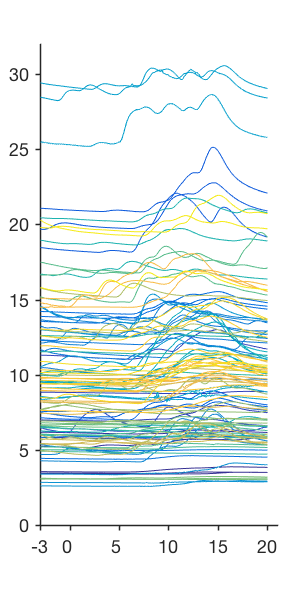

create_figure('grand average');

colormap('default');
cmap = colormap;

for i = 1:41
    hold on;
    plot(signal{i}.cond{6,2}', 'LineWidth', 1, 'color', cmap(round(i*1.5),:));
end
set(gcf, 'position', [360   108   306   590]);
set(gca, 'TickDir', 'out', 'linewidth', 1.5, 'xtick', [0 75:125:600], 'XTickLabel', [-3 0:5:20], 'ylim', [0 32]);

savename = fullfile(figdir, 'grandaverage_step1.pdf');
pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

## Step 2

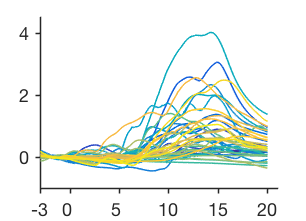


create_figure('grand average');
hold on;

for i = 1:41
    hold on;
    plot(signal_m{6,2}(i,:)', 'LineWidth', 1.5, 'color', cmap(round(i*1.5),:));
end
set(gcf, 'position', [360   477   306   221]);
set(gca, 'TickDir', 'out', 'TickLength', [.02 .02], 'linewidth', 1.5, 'xtick', [0 75:125:600], 'XTickLabel', [-3 0:5:20], 'ylim', [-1 4.5]);
savename = fullfile(figdir, 'grandaverage_step2.pdf');
pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

## Step 3

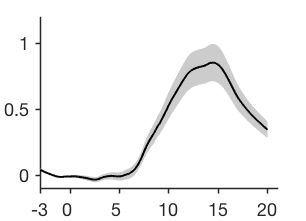

create_figure('grand average');
hold on;

%plot(mean(signal_m{6,2})', 'LineWidth', 2, 'color', 'k');
wani_plot_shading(1:numel(mean(signal_m{6,2})), mean(signal_m{6,2}), ste(signal_m{6,2}), 'color', 'k', 'color_shade', [.8 .8 .8]);

set(gcf, 'position', [360   477   306   221]);
set(gca, 'TickDir', 'out', 'TickLength', [.02 .02], 'linewidth', 1.5, 'xtick', [0 75:125:600], 'XTickLabel', [-3 0:5:20], 'ylim', [-.1 1.2]);
savename = fullfile(figdir, 'grandaverage_step3.pdf');
pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

## Each temperature level

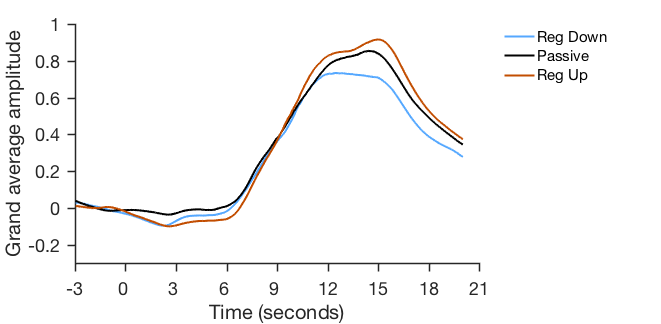

close all;
temp = {'44', '45', '46', '47', '48', '49'};

j = 6; % 49 celcius degree - you can change this value
x = 1:576;
create_figure('shading');
cols = [0.3333    0.6588    1.0000
    0         0         0
    0.7608    0.3020         0];
for i = 1:3
    hold on;
    plot(x, mean(signal_m{j,i}), 'color', cols(i,:), 'linewidth', 2);
end

set(gcf, 'position', [50   126   661   324]);
set(gca, 'ylim', [-.3 1], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (0:3:24)*25);
set(gca, 'XTickLabel', get(gca, 'XTick')./25-3);
h = legend('Reg Down', 'Passive', 'Reg Up'); 
set(h, 'fontsize', 15, 'box', 'off', 'Location', 'northeastoutside');
xlabel('Time (seconds)');
ylabel('Grand average amplitude');

## All temperature; SCR

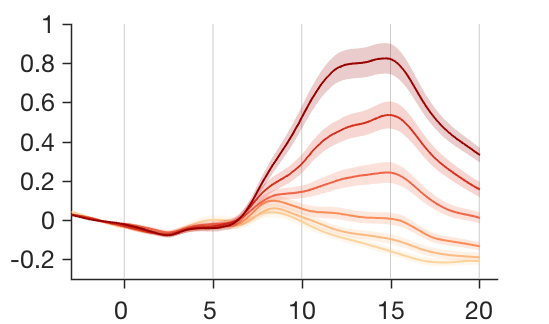

close all;

x = 1:576;
create_figure('shading');
cols = [0.9922    0.8314    0.6196
    0.9922    0.7333    0.5176
    0.9882    0.5529    0.3490
    0.9373    0.3961    0.2824
    0.8431    0.1882    0.1216
    0.6000         0         0];

for i = (3:5:24)*25
    line([i i], [-.3 1], 'col', [.8 .8 .8], 'linewidth', 1);
end

for i = 1:6
    hold on;
    wani_plot_shading(x, mean(cat(1,signal_m{i,:})), ste(cat(1,signal_m{i,:})), 'color', cols(i,:), 'alpha', .2);
    % wani_plot_shading(x, mean(cat(1,signal_m{i,:})), repmat(wsbar(cat(1,signal_m{i,:})), 1, size(cat(1,signal_m{i,:}),2)), 'color', cols(i,:), 'alpha', .2);
    % plot(x, mean(cat(1,signal_m{i,:})), 'color', cols(i,:), 'linewidth', 2);
end

set(gcf, 'position', [50   126   549   324]);
set(gca, 'ylim', [-.3 1], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (3:5:24)*25, 'ytick', -.2:.2:1);
set(gca, 'XTickLabel', get(gca, 'XTick')./25-3);
set(gca, 'fontSize', 25);
% h = legend('44.3', '45.3', '46.3', '47.3', '48.3', '49.3');
% set(h, 'fontsize', 15, 'box', 'off', 'Location', 'northeastoutside');
% xlabel('Time (seconds)', 'fontsize', 18);
% ylabel('Grand average amplitude', 'fontsize', 18);

savename = fullfile(figdir, 'Temp_all_grandavg_full.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

## REG average over temp (not sure if we need this for now)

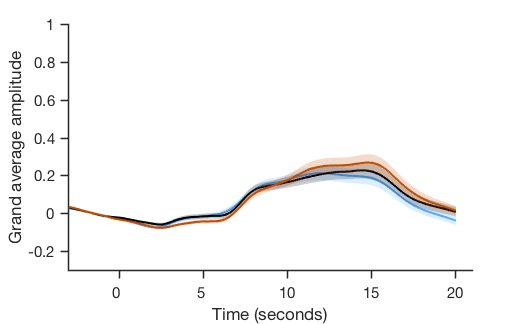

close all;

x = 1:576;
create_figure('shading');
cols = [0.3333    0.6588    1.0000
    0         0         0
    0.7608    0.3020         0];

for i = 1:3
    hold on;
    wani_plot_shading(x, mean(cat(1,signal_m{:,i})), ste(cat(1,signal_m{:,i})), 'color', cols(i,:), 'alpha', .2);
    % plot(x, mean(cat(1,signal_m{:,i})), 'color', cols(i,:), 'linewidth', 2);
end

set(gcf, 'position', [50   126   522   324]);
set(gca, 'ylim', [-.3 1], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (3:5:24)*25, 'ytick', -.2:.2:1);
set(gca, 'XTickLabel', get(gca, 'XTick')./25-3);
set(gca, 'fontSize', 15);
% h = legend('Reg Down', 'Passive', 'Reg Up'); 
% set(h, 'fontsize', 15, 'box', 'off', 'Location', 'northeastoutside');
xlabel('Time (seconds)');
ylabel('Grand average amplitude');